# (1). Import and Visualize Bruker Data

### Requirement

Download* rbnmr (*[RBNMR](https://www.mathworks.com/matlabcentral/fileexchange/40332-rbnmr)) and add these two functions to this folder: "rbnmr.m" and "plotbnmr.m". These matlab functions are provided by [Nils Nyberg](https://www.mathworks.com/matlabcentral/profile/authors/263929). These functions make it easy to read Bruker format processed NMR data into the workspace memory of matlab and to plot the data. It supports one and two-dimensional data.

### Import Bruker NMR data

The 1H [Bruker NMR](http://www.nmragenda-leiden.nl/static/Bruker_manual_4.1.4/topspin_pdf/Bruker_NMR_Data_Formats.pdf) data is read into [MATLAB structures](https://www.mathworks.com/help/matlab/structures.html). A structure array is a data type that groups related data using data containers called fields. In this example we use rbnmr function to import the data. The Ethyl_Crotionate_Data is kindly provided by Prof. Ilya Kuprov, University of Southampton.

path = pwd;
Bruker_Datafolder = 'Ethyl_Crotonate_Data';
fullpath = fullfile(path, Bruker_Datafolder);
disp(fullpath);

C:\Users\hjooya\Desktop\NMR_GitHub\L1_Import_Process_Bruker_Data\Ethyl_Crotonate_Data


NMRdata=rbnmr(fullpath);

Searching for data files with a perl script...
OK! Here we go...
  1/1   ./pdata/1/1r                                  trans-ethyl crotonate in CDCl3


We can plot the spectrum by pulling the "X-axis" and "Data" from the above structured data.

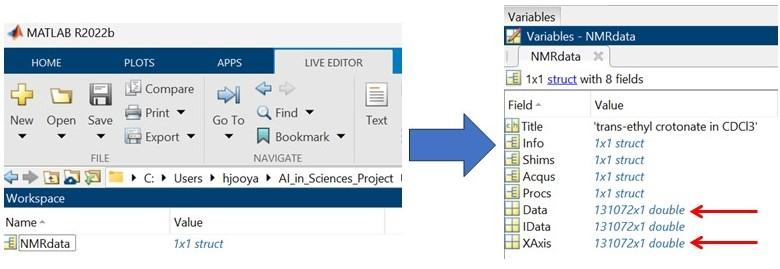

### Visualize the spectrum

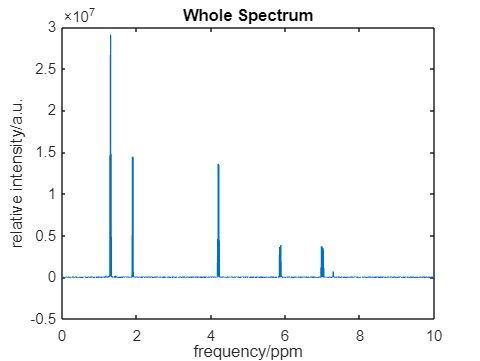

freq=NMRdata.XAxis;
sig=NMRdata.Data;

figure
plot(freq,sig)
title('Whole Spectrum')
xlabel('frequency/ppm')
ylabel('relative intensity/a.u.')

### Select regions and plot

We can now select different regions on the plot for further processing (e.g. integration)

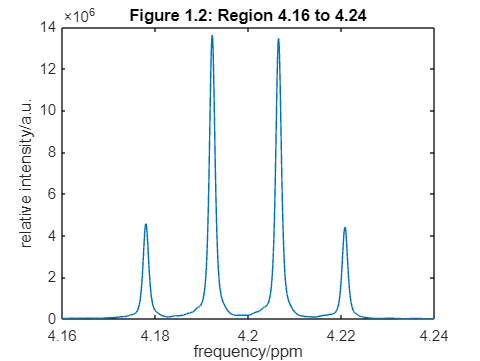

% Select and plot the first region from 4.16 to 4.24
idx1 = freq >= 4.16 & freq <= 4.24;

figure; 
plot(freq(idx1), sig(idx1));
xlabel('frequency/ppm');
ylabel('relative intensity/a.u.');
title('Figure 1.2: Region 4.16 to 4.24');

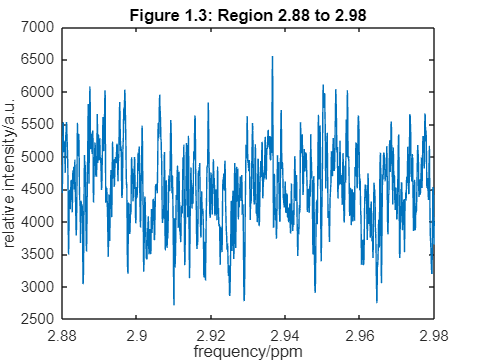


% Select and plot the second region from 2.88 to 2.98
idx2 = freq >= 2.88 & freq <= 2.98;

figure; 
plot(freq(idx2), sig(idx2));
xlabel('frequency/ppm');
ylabel('relative intensity/a.u.');
title('Figure 1.3: Region 2.88 to 2.98');